# Comparison of discrete controller design methods for systems with big dead time  -  Advanced topic 

Control is commonly implemented in discrete time. The basic definition and usage of discrete models in MATLAB is shown in files ***discrete_models_and_usage.mlx ***and ***discretization_and_bode.mlx***

PID controller design in sampled systems is discussed in file

***discrete_models_and_discrete_PID controller_design.mlx***

Files ***Youla_discrete_controller_design.mlx***, ***Dead_beat_controller_design.mlx*** and ***Smith_predictor_controller_design.mlx*** show design methods which give faster behaviour than PID design when the  process contains big dead time.

The aim of this file is to compare and evaluate these design methods and to illustrate their sensitivity to uncertainty in the dead time through an example.

Description of the methods is not repeated here.

**Similar files and the toolbox**

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by  Ruth Bars, László Keviczky, Budapest University of Technology and Economics                                                    

and  J.A. Rossiter, University of Sheffield

                                            

Reference: Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász,

Springer, 2019                     

## Table of contents

- The block diagram of the control system

- Example comparing several design approaches

- Student tasks

## 1.The block diagram of the control system

The block diagram of the control system is given below. 

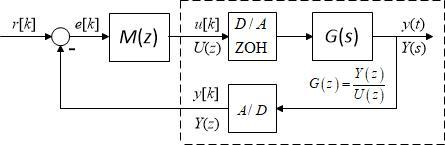

$R\left(z\right)$ is the z-transform of the the target reference signal, $Y\left(z\right)$ is the z-transform of the output and  $U\left(z\right)$ is the z-transform of the input signal. 

The assumption is made that the model may be first provided in continuous time form, as most real systems are continuous. The output is sampled and at the input of the plant zero order hold is applied. The controller is discrete, its output values are calculated in the sampling instants and the zero order hold ZOH provides the continuous input at the input of the process. $G\left(z\right)$ is the pulse transfer function of the plant (the parts within the dotted box are approximated as $G\left(z\right)$) , $M\left(z\right)$ is the pulse transfer function of the controller.

The aim is to design and compare compensators as follows:

a. PIPD controller with pole cancellation technique for about 60 degrees of phase margin.

b. Dead beat controller avoiding intersampling ripples.

c. Smith predictor controller.

d. Youla parameterised controller.

## 2. Example

This file is an exemplar of how to go about the comparison task and thus utlises just a single example. The transfer function of the plant is 

$G\left(s\right)=\frac{2\;e^{-20s} }{\left(1+4s\right)\left(1+6s\right)\left(1+10s\right)}$; 

The sampling time is $T_s =2$ and the reference signal is a unit step. 

The sections below undertake the specific designs and comparisons. It is considers analysis of the control performance in the case of uncertainty, here specifically an error in the assumed  dead time of 20.

#### 2.1 First determine the pulse transfer function of the plant.

disp('THE PULSE TRANSFER FUNCTION OF THE PLANT')

THE PULSE TRANSFER FUNCTION OF THE PLANT


s=zpk('s');
Gs=2/((1+4*s)*(1+6*s)*(1+10*s));
disp('Transfer function of the continuous process')

Transfer function of the continuous process


Gs1=Gs*exp(-20*s)

Gs1 =
 
                        0.0083333
  exp(-20*s) * ---------------------------
               (s+0.25) (s+0.1667) (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties


T=2 ;        %sampling time
z=zpk('z',T);
Gd=c2d(Gs,T);   %or alternatively Gd1=c2d(G1,T,'zoh'), discrete model
disp('Pulse transfer function of the sampled process')

Pulse transfer function of the sampled process


Gd1=Gd*z^-10

Gd1 =
 
     0.0086104 (z+0.2061) (z+2.894)
  -------------------------------------
  z^10 (z-0.8187) (z-0.7165) (z-0.6065)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('Process poles, zeros and gain')

 ***********************


Extracting poles and zeros


[zeros,poles,k1]=zpkdata(Gd,'v')

zeros =    -0.2061
   -2.8935


poles =     0.8187
    0.7165
    0.6065


k1 = 0.0086

disp('Step response of the process')

Step response of the process


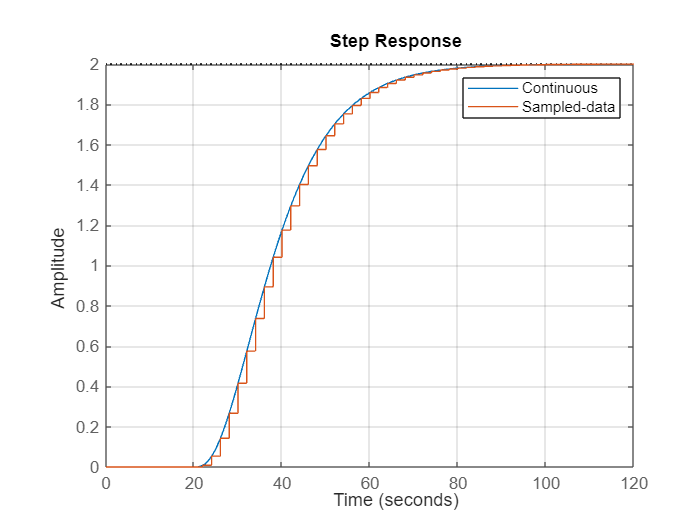

step(Gs1,Gd1),grid
legend('Continuous','Sampled-data')

Hence, the pulse transfer function of the plant is:


$$\textrm{Gd}\left(z\right)=\frac{0\ldotp 0086104\;\left(z+0\ldotp 2061\right)\left(z+2\ldotp 894\right)}{\left(z-0\ldotp 8185\right)\left(z-0\ldotp 7165\right)\left(z-0\ldotp 6065\right)}\;z^{-10}$$


#### 2.2 Design a PIPD controller with pole cancellation technique for about 60 degrees of phase margin

PID controller design in sampled systems is discussed in file ***discrete_models_and_discrete_PID controller_design.mlx ***so not repeated here. Rather solely the coe is provided.

disp('Section 2.2: PIPD CONTROLLER')

Section 2.2: PIPD CONTROLLER


MPID=(z-poles(1))*(z-poles(2))/(z*(z-1));
L=minreal(MPID*Gd,0.001);
L1=L*z^-10;
[mag,phase,w]=bode(L1);
k=margin(mag,phase-60,w);

k = 0.3940

disp('Pulse transfer function of the PIPD controller')

Pulse trnsfer function of the controller


MPID1=k*MPID

MPID1 =
 
  0.39397 (z-0.8187) (z-0.7165)
  -----------------------------
             z (z-1)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties


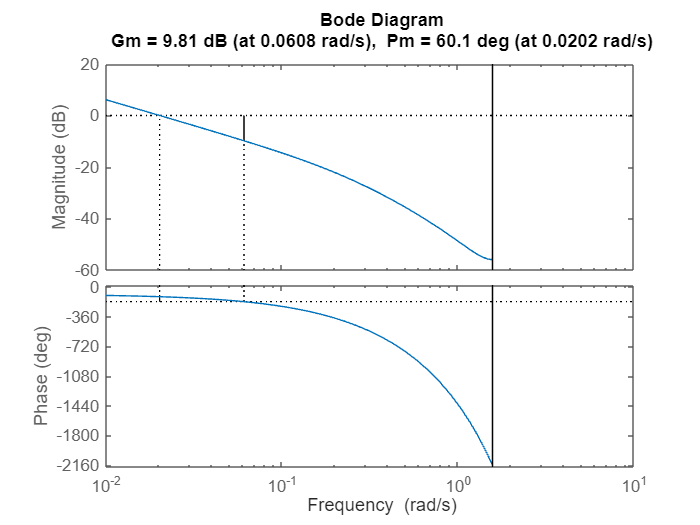

L2=k*L1;
margin(L2)

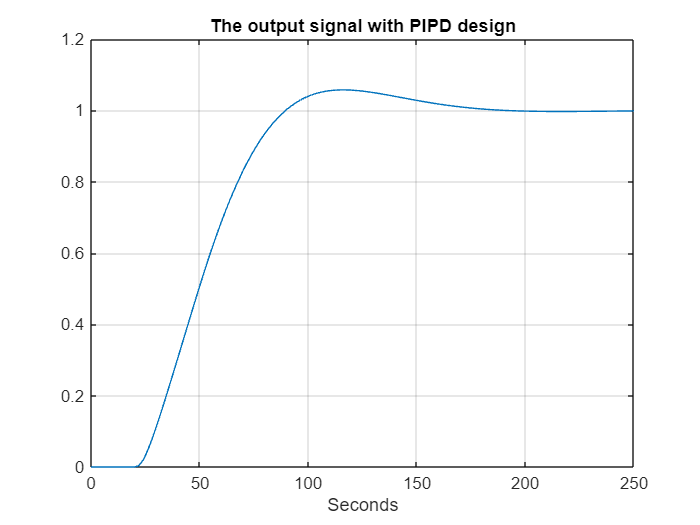

t=0:T:250;
ypid=step(L2/(1+L2),t);
plot(t,ypid),grid
title('The closed-loop output signal with PIPD design')
xlabel('Seconds')

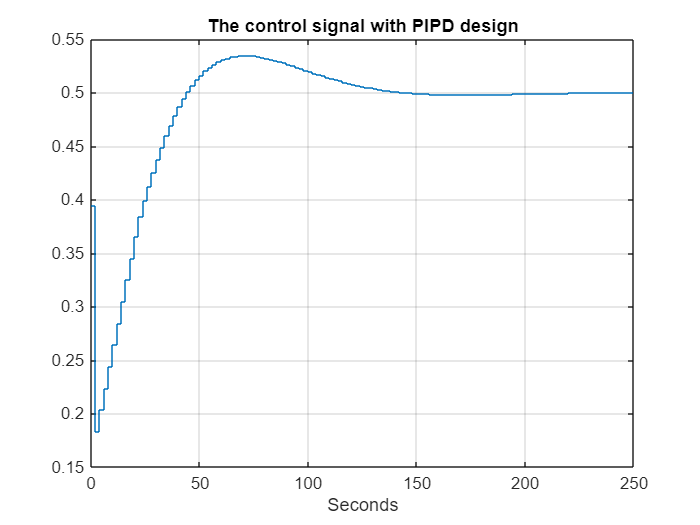

upid=step(MPID1/(1+L2),t);
stairs(t,upid),grid
title('The closed-loop control signal with PIPD design')
xlabel('Seconds')

**Performance with uncertainty**: It is seen that the settling time is about 200sec. In steady state the output is settled to 1, to the value of the reference signal. Analyse the control performance if in reality the dead time is 16 or 24 (instead of the considered 20 in the controller design).

disp('Analyse the behaviour in case of mismatch in the dead time')

Analyse the behaviour in case of mismatch in the dead time


disp('The dead time of the model is 20sec, in reality it is 16 or 24 sec')

The dead time of the model is 20sec, in reality it is 16 or 24 sec


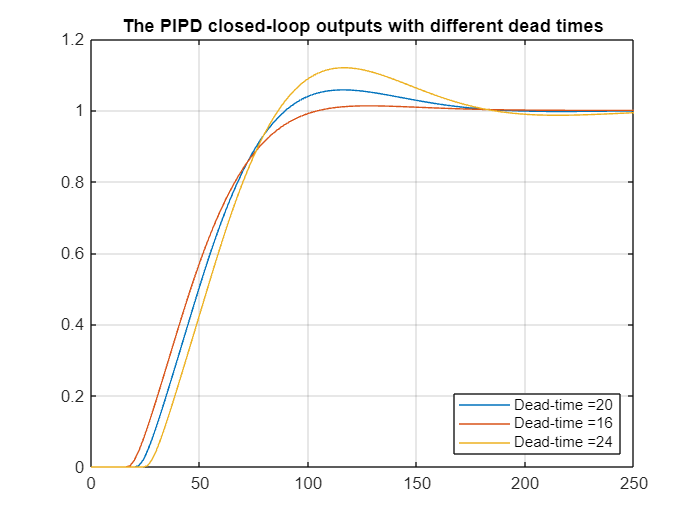

L2mismatch1=k*L*z^-8;
L2mismatch2=k*L*z^-12;

ypidmis1=step(L2mismatch1/(1+L2mismatch1),t);
ypidmis2=step(L2mismatch2/(1+L2mismatch2),t);
plot(t,ypid,t,ypidmis1,t,ypidmis2),grid
title('The PIPD closed-loop outputs with different dead times')
legend('Dead-time =20','Dead-time =16','Dead-time =24','Location','Southeast')

It is seen that the design is tolerable for these mismatches in the dead time.

#### 2.3 Design a dead beat controller avoiding intersampling ripples

More information on this design approach is in the file ***Dead_beat_controller_design.mlx ***and just a summary is given here.

The pulse transfer function of the plant is given as


$$G\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}\;z^{-d} =\frac{B_+ \left(z\right)B_- \left(z\right)}{A\left(z\right)}{\;z}^{-d}$$


where $B_+ \left(z\right)$ contains the cancellable factor and  $B_- \left(z\right)$ contains the non-cancellable factor of the numerator of the pulse transfer function. It has to be ensured that $B_- \left(z\right)|_{z=1} =1$.

Now the pulse transfer function of the closed loop is prescribed as

$T\left(z\right)={B_{-\;\;} \left(z\right)\;\;z}^{-d}$.

The resulting pulse transfer function between the output and the reference signal is


$$\frac{M\left(z\right)G\left(z\right)}{1+M\left(z\right)G\left(z\right)}=T\left(z\right)={B_{-\;\;} \left(z\right)\;\;z}^{-d}$$


Hence


$$M\left(z\right)=\frac{A\left(z\right)}{B_+ \left(z\right)\left(1-B_- \left(z\right)\;\;z^{-d} \right)}$$


It is advised to give the polynomials with the shift operator $z^{-1}$.

disp('Section 2.3: DEAD BEAT CONTROLLER')

Section 2.3: DEAD BEAT CONTROLLER


A=(1-poles(1)*z^-1)*(1-poles(2)*z^-1)*(1-poles(3)*z^-1);
Bminus=(1-zeros(1)*z^-1)*(1-zeros(2)*z^-1)/((1-zeros(1))*(1-zeros(2)));
Bplus=k1*(1-zeros(1))*(1-zeros(2));
Mdead=A/(Bplus*(1-Bminus*z^-11))

Mdead =
 
                                                         24.73 z^13 (z-0.8187) (z-0.7165) (z-0.6065)
  ----------------------------------------------------------------------------------------------------------------------------------------------------------
  z^3 (z-1) (z+0.911) (z+0.2061) (z^2 + 1.601z + 0.8476) (z^2 - 1.722z + 0.9923) (z^2 + 0.9584z + 0.8887) (z^2 - 0.9726z + 0.9695) (z^2 + 0.01812z + 0.9333)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.


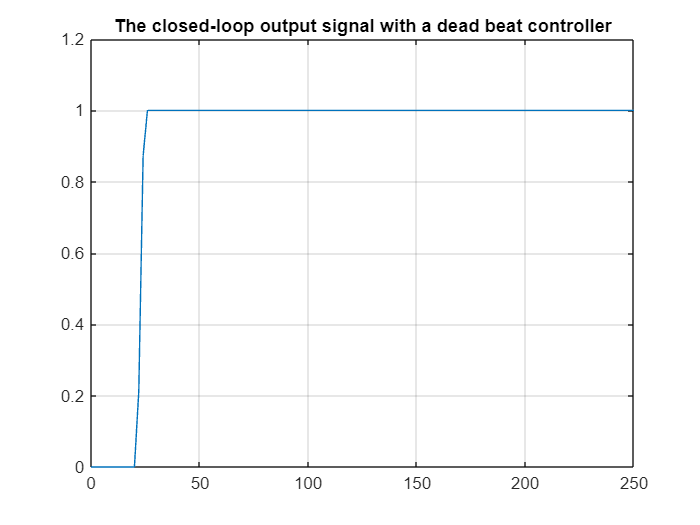

L=minreal(Mdead*Gd1,0.001);

ydead=step(L/(1+L),t);
plot(t,ydead),grid
title('The closed-loop output signal with a dead beat controller')

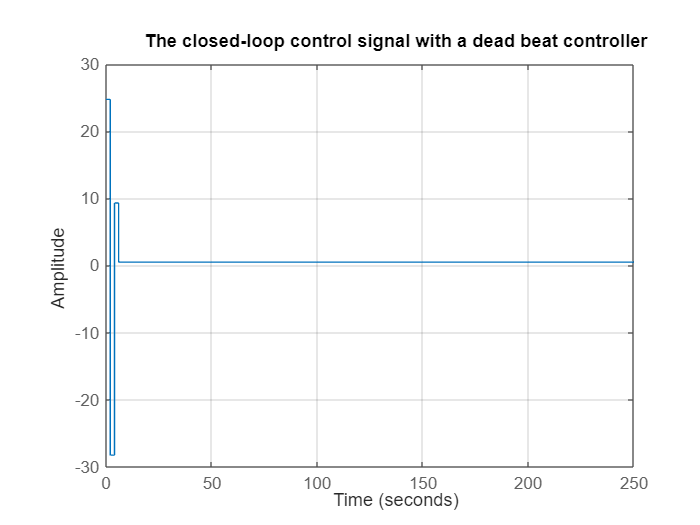

xlabel('Seconds')

step(Mdead/(1+L),t),grid 
title('The closed-loop control signal with a dead beat controller')

xlabel('Seconds')

It is seen that the output signal is settled within 28 sec, much faster than with PID controller.

Analyse the control performance if in reality the dead time is 18 or 22 (instead of the considered 20 in the controller design). (These are smaller mismatch values than in case of PIPD control.)

**Performance with uncertainty**:  Analyse the control performance if in reality the dead time is 10 or12 samples as opposed to the 11  considered 20 in the controller design.

disp('Analyse the behaviour in case of mismatch in the dead time')

Analyse the behaviour in case of mismatch in the dead time


disp('The dead time of the model is 20sec, in reality it is 18 or 22 sec')

The dead time of the model is 20sec, in reality it is 18 or 22 sec


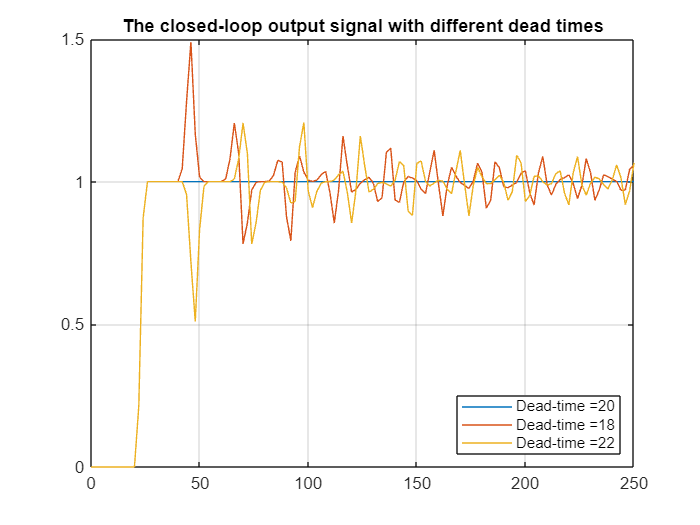

Mmis1=A/(Bplus*(1-Bminus*z^-10));
Mmis2=A/(Bplus*(1-Bminus*z^-12));
Lmis1=minreal(Mmis1*Gd1,0.001);
Lmis2=minreal(Mmis2*Gd1,0.001);
ydeadmis1=step(Lmis1/(1+Lmis1),t);
ydeadmis2=step(Lmis2/(1+Lmis2),t);
plot(t,ydead,t,ydeadmis1,t,ydeadmis2),grid
xlabel('Seconds')
title('The closed-loop output signal with different dead times')
legend('Dead-time =20','Dead-time =18','Dead-time =22','Location','Southeast')

It is seen that the dead beat algorithm is very sensitive to the mismatch in the dead time.

#### 2.4 Design Smith predictor controller

More on this design approach is in the file ***Smith_predictor_controller_design.mlx.***

If the process contains big dead time, with PID controller the control system will be slow. O.J. Smith suggested a control algorithm which behaves as if the dead time would have been located outside of the feedback loop. The controller $M_+$ is designed for the dead time free process, and the controller is realised with the algorithm   


$$M\left(z\right)=\frac{M_+ \left(z\right)}{1+M_+ {\left(z\right)\;G}_+ \left(z\right)\left(1-z^{-d} \right)}$$


disp('Section 2.4: SMITH PREDICTOR CONTROLLER')

Section 2.4: SMITH PREDICTOR CONTROLLER


disp('Design a PIPD controller for the delay free process with a design objective 60 degree phase margin')

Design a PIPD controller for the delay free process with a design objective 60 degree phase margin


Mplus=(z-poles(1))*(z-poles(2))/((z-1)*z);
Lplus=minreal(Mplus*Gd,0.001);
[mag,phase,w]=bode(Lplus);
k2=margin(mag,phase-60,w);
disp('PID controller in the delay free control system')

PID controller in the delay free control system


Mplus1=k2*Mplus

Mplus1 =
 
  1.8924 (z-0.8187) (z-0.7165)
  ----------------------------
            z (z-1)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties


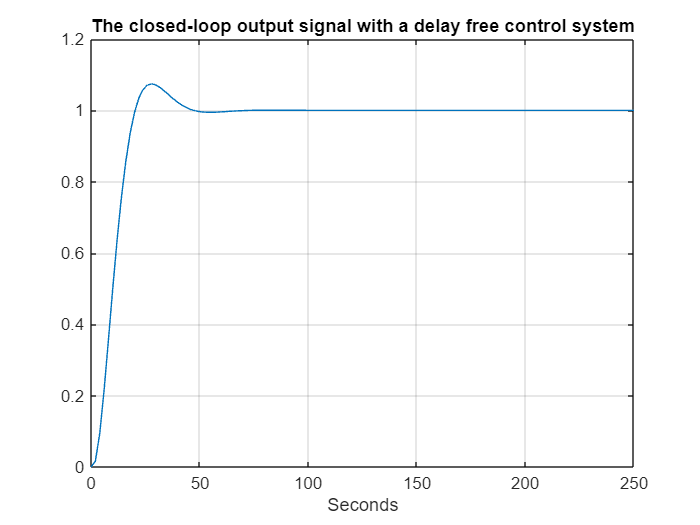

Lplus1=k2*Lplus;

ydelfree=step(Lplus1/(1+Lplus1),t);
plot(t,ydelfree),grid
title('The closed-loop output signal with a delay free control system')
xlabel('Seconds')

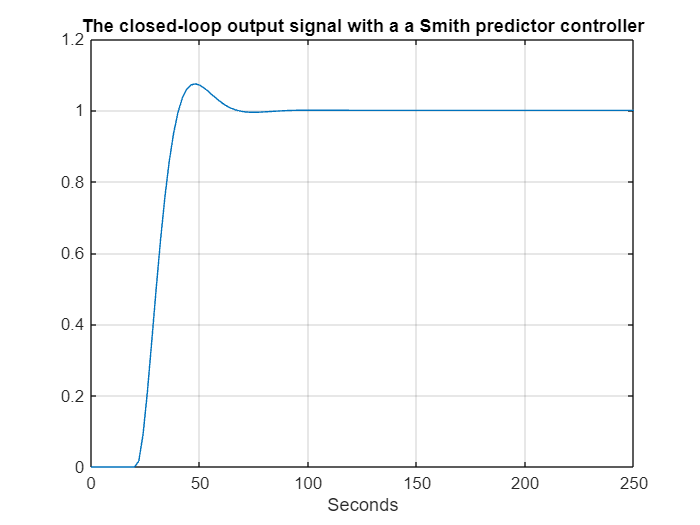


Msmith=Mplus1/(1+Mplus1*Gd*(1-z^-10));
Lsmith=minreal(Msmith*Gd1,0.001);
ysmith=step(Lsmith/(1+Lsmith),t);
plot(t,ysmith),grid
title('The closed-loop output signal with a a Smith predictor controller')
xlabel('Seconds')

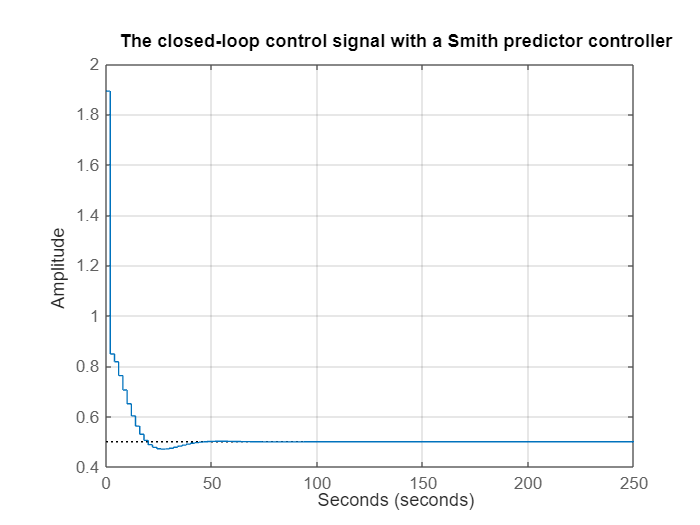


step(Msmith/(1+Lsmith),t),grid   
title('The closed-loop control signal with a Smith predictor controller')
xlabel('Seconds')

It is seen that the output is  similar to the output of the delay free system, but it is shifted by the dead time. The settling time is about 60 sec. 

**Performance with uncertainty**:  Analyse the control performance if in reality the dead time is 16 or 24 (instead of the considered 20 in the controller design).

disp('Analyse the behaviour in case of mismatch in the dead time')

Analyse the behaviour in case of mismatch in the dead time


disp('The dead time of the model is 20sec, in reality it is 16 or 24 sec')

The dead time of the model is 20sec, in reality it is 16 or 24 sec


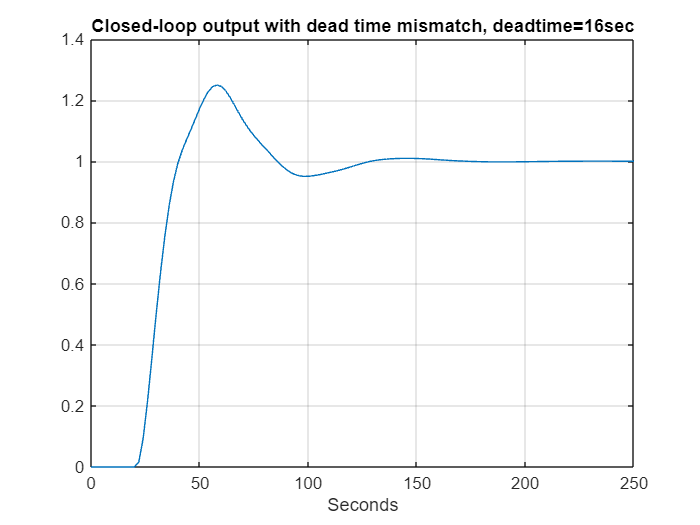

Msmith1=Mplus1/(1+Mplus1*Gd*(1-z^-8));
Msmith2=Mplus1/(1+Mplus1*Gd*(1-z^-12));
Lsmith1=minreal(Msmith1*Gd1,0.001);
Lsmith2=minreal(Msmith2*Gd1,0.001);
ymis1=step(Lsmith1/(1+Lsmith1),t);

plot(t,ymis1),grid
xlabel('Seconds')
title('Closed-loop output with dead time mismatch, deadtime=16sec')

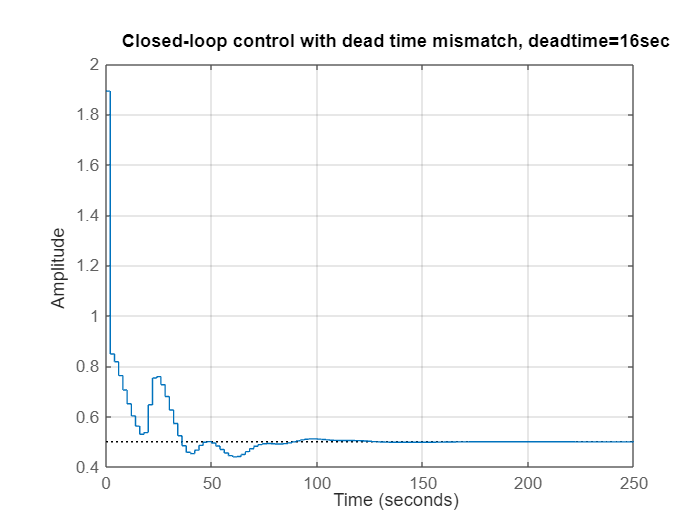


step(Msmith1/(1+Lsmith1),t),grid
title('Closed-loop control with dead time mismatch, deadtime=16sec')

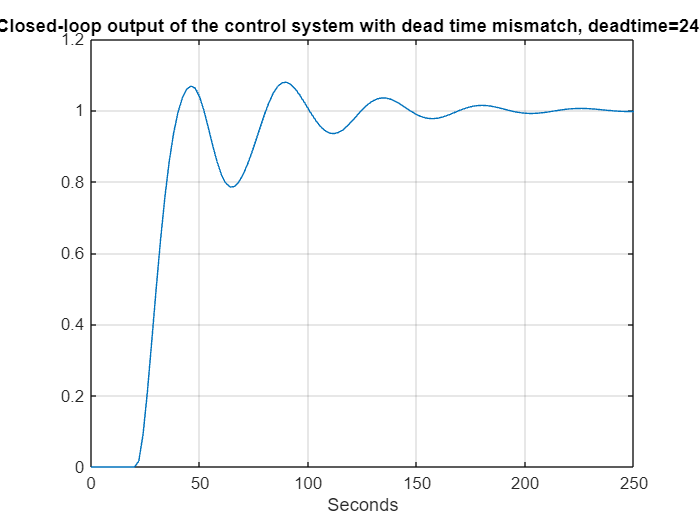


ymis2=step(Lsmith2/(1+Lsmith2),t);
plot(t,ymis2),grid
xlabel('Seconds')
title('Closed-loop output of the control system with dead time mismatch, deadtime=24sec')

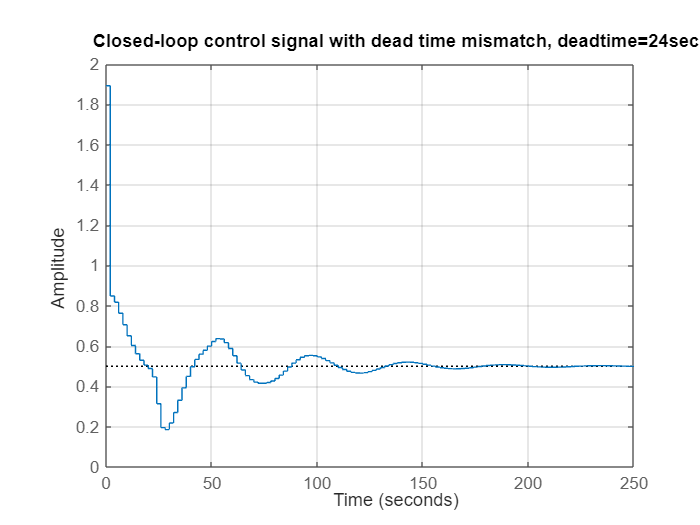


step(Msmith2/(1+Lsmith2),t),grid
title('Closed-loop control signal with dead time mismatch, deadtime=24sec')

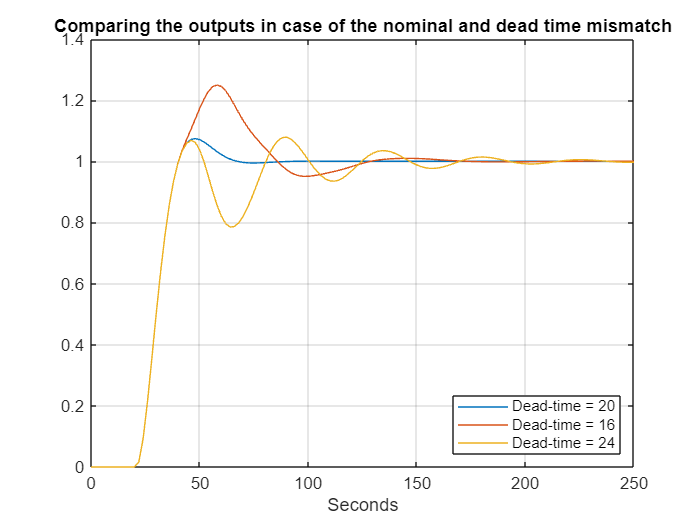


plot(t,ysmith,t,ymis1,t,ymis2),grid
xlabel('Seconds')
title('Comparing the closed-loop outputs in case of dead time mismatch')
legend('Dead-time = 20','Dead-time = 16', 'Dead-time = 24','Location','Southeast')

It is seen that the control system is quite tolerable for the considered mismatch in the dead time and is faster than the PIPD control. 

#### 2.5 Design Youla parameterised controller

More information on this design approach is in ***Youla_discrete_controller_design.mlx.***

The relationship between the u control signal and the r reference signal supposing no disturbances is given by the following relationship with the pulse transfer functions: 


$$\frac{U\left(z\right)}{R\left(z\right)}=\frac{M\left(z\right)}{1+G\left(z\right)M\left(z\right)}=Q\left(z\right)$$
      

The pulse transfer function *Q* is called YOULA parameter. The resulting transfer function between the output signal y and the reference signal r  is  *T*(*z*)=*Q*(*z*)*G*(*z*)*. * If *G* is stable, any stable *Q* ensures a stable closed loop control circuit. 

The series *M*(z) controller as given with the YOULA parameter as

$M\left(z\right)=\frac{Q\left(z\right)}{1-Q\left(z\right)G\left(z\right)}$.

The pulse transfer function G of the process has to be separated to the cancellable $G_+ \left(z\right)$ and the non-cancellable $G_- \left(z\right)$ components. The discrete dead time is denoted by *d*.


$$G=G_+ G_- z^{-d}$$


In case of lag elements there is always a  $z^{-1\;}$ term, so the discrete  *d*  dead time is calculated as the ratio of the $T_d$ physical dead time and the $T_s$ sampling time plus 1. Preferably choose the sampling time so that ratio $T_d /T_s$ be integer. 

The static gain of $G_- \left(z\right)$ should be 1 to ensure accurate reference signal tracking in steady state. Thus $G_- \left(z=1\right)=1\ldotp$

The dead time can not be cancelled. The zero of the pulse transfer function of the process which is outside of the unit circle also can not be cancelled, as this would result an unstable pole in the controller. Also it is not expedient to cancel zeros which are on the left side of the unit circle, as this would introduce a pole in the controller causing intersampling oscillations in the control system.  

The Youla parameter performs the inverse of the invertible part of the transfer function of the model of the process.


$$Q=G_+^{-1}$$


It is mentioned that with filters the dynamics of reference signal tracking and disturbance rejection can be made different. The control structure enhanced with the filters is shown in the figure below.

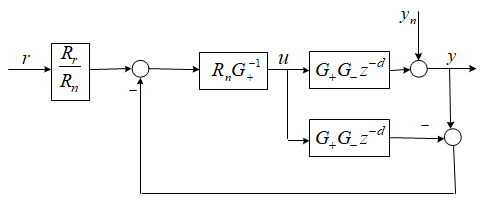

The Youla parameter now is given as 


$$Q={R_n G}_+^{-1}$$


If there is no disturbance and there is no mismatch between the process and its model then the relationship between the output and tzhe reference signal can be calculated in open loop as


$$y=R_r G_- z^{-d}$$


With the filters the effects of plant/model mismatch can also be influenced. The IMC structure  above can be transformed to the usual control structure as shown in the next figure.

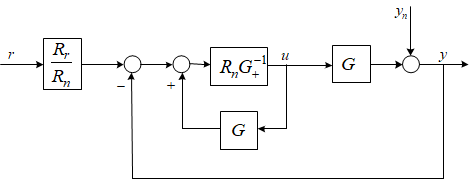

The Youla controller in the closed loop now can be given as


$$M=\frac{R_n G_+^{-1} }{1-R_n G_- z^{\ldotp d} }=\frac{Q}{1-\textrm{QG}}$$


Let us analyse the behaviour of the Youla controller, analyse the effect of different filters, simulate the behaviour without and with dead time mismatch.

Remark: The filters should ensure the realisability of the Youla parameter. If they are built of first order lags, do not introduce zeros to their pulse transfer functions, so it is advised to build the filters multiplying the pulse transfer functions of first order lag elements.

disp('Section 2.5: YOULA CONTROLLER')

Section 2.5: YOULA CONTROLLER


% Separate the pulse transfer function of the plant to cancellable (Gplus)
% and non-cancellable (Gminus) parts.

% Uncomment the relevant lines to see more detail of the designs.

Gd;
Gminus=(z-zeros(1))*(z-zeros(2))/(((1-zeros(1))*(1-zeros(2))));
Gplus=k1*(1-zeros(1))*(1-zeros(2))/((z-poles(1))*(z-poles(2))*(z-poles(3)));
%Check if this separation gives the whole pulse transfer function
G_Gplus=Gminus*Gplus

G_Gplus =
 
   0.0086104 (z+0.2061) (z+2.894)
  --------------------------------
  (z-0.8187) (z-0.7165) (z-0.6065)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties



%disp('Choose the filters')
Rrd=c2d(1/(1+2*s),T);
Rrd1=Rrd*Rrd*Rrd;
Rnd=c2d(1/(1+3*s),T);
Rnd1=Rnd*Rnd*Rnd;
%Another choice
% Rnd1=z^-3
% Rrd1=z^-3

disp('The Youla parameter')

The Youla parameter


Q=Rnd1/Gplus

Q =
 
  2.8491 (z-0.8187) (z-0.7165) (z-0.6065)
  ---------------------------------------
               (z-0.5134)^3
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties


Gd1=Gd*z^-10;
M=Q/(1-Q*Gd1);

disp('The controller in the closed loop')

The controller in the closed loop


M=minreal(M,0.001)

M =
 
                                                      2.8491 z^10 (z-0.8187) (z-0.7165) (z-0.6065)
  ----------------------------------------------------------------------------------------------------------------------------------------------------
  (z+0.6588) (z-1) (z+0.2061) (z^2 + 1.124z + 0.4587) (z^2 - 1.755z + 0.9275) (z^2 + 0.5672z + 0.5241) (z^2 - 1.099z + 0.771) (z^2 - 0.2423z + 0.6267)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.


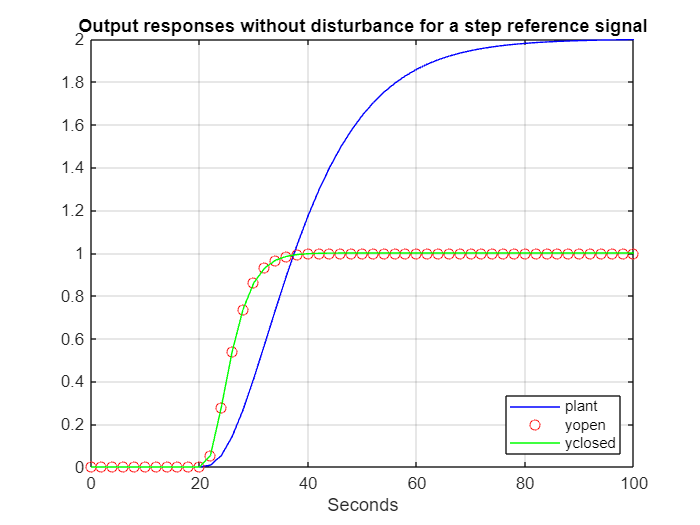

% disp('The closed loop pulse transfer function')
Tclosed=(Rrd1/Rnd1)*M*Gd1/(1+M*Gd1);
Tclosed=minreal(Tclosed,0.001);
%disp('The resulting pulse transfer function from the forward path')
Tres=minreal((Rrd1/Rnd1)*Q*Gd1,0.0001);
t=0:T:100;

y=step(Tres,t);
yplant=step(Gd1,t);
yclosed=step(Tclosed,t);
plot(t,yplant,'b-',t,y,'ro',t,yclosed,'g-'),grid
title('Output responses without disturbance for a step reference signal')
legend('plant','yopen','yclosed','Location','Southeast')
xlabel('Seconds')

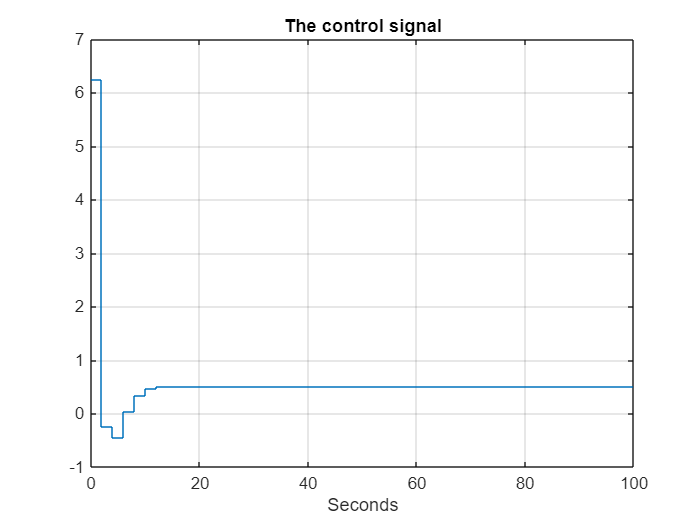


U=minreal((Rrd1/Rnd1)*Q,0.0001);
u=step(U,t);
stairs(t,u),grid
title('The control signal')
xlabel('Seconds')

It is seen that the behaviour became faster and the control algorithm calculated in open loop and in closed loop gives the same result.

**Performance with uncertainty**: Analyse the control performance if in reality the dead time is 16 or 24 (instead of the considered 20 in the controller design).

disp('Analyse the behaviour in case of mismatch in the dead time')

Analyse the behaviour in case of mismatch in the dead time


disp('The dead time of the model is 20sec, in reality it is 16 or 24 sec')

The dead time of the model is 20sec, in reality it is 16 or 24 sec


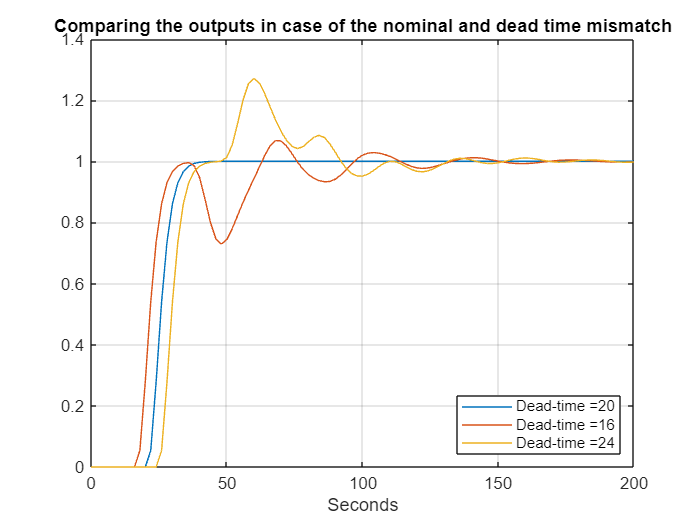

Tclosed=(Rrd1/Rnd1)*M*Gd1/(1+M*Gd1);
Tclosed=minreal(Tclosed,0.001);
Gd1mis1=Gd*z^-8;
Gd1mis2=Gd*z^-12;
Tclosedmis1=(Rrd1/Rnd1)*Q*Gd1mis1/(1-Q*Gd*(z^-10-z^-8));
Tclosedmis1=minreal(Tclosedmis1,0.001);
Tclosedmis2=(Rrd1/Rnd1)*Q*Gd1mis2/(1-Q*Gd*(z^-10-z^-12));
Tclosedmis2=minreal(Tclosedmis2,0.001);
t=0:T:200;

yclosed=step(Tclosed,t);
ymisy1=step(Tclosedmis1,t);
ymisy2=step(Tclosedmis2,t);
plot(t,yclosed,t,ymisy1,t,ymisy2),grid
title('Comparing the outputs in case of the nominal and dead time mismatch')
xlabel('Seconds')
legend('Dead-time =20','Dead-time =16','Dead-time =24','Location','Southeast')

It is seen that the algorithm handles this mismatch in the dead time and after 100 sec the transients are settled.

## 3. Student tasks

- Analyse the effect of different filters to mismatch in dead time and other parameters.

- Analyse and compare the behaviour of the different algorithms considering also plant/model mismatch using the corresponding simulink models.

- Try different scenarios and models.

- Overlay the different approaches on the same figures to allow effective comparison.